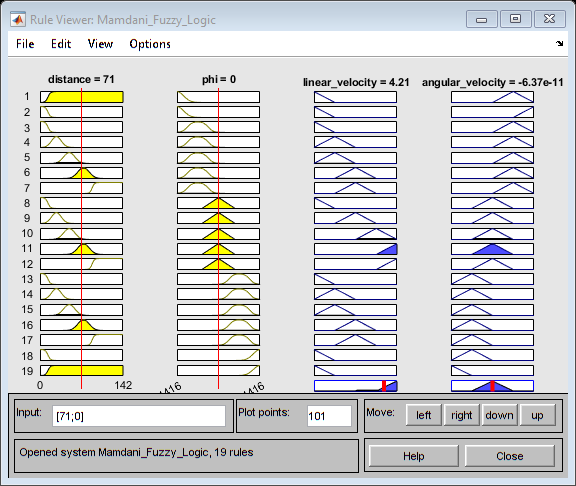

clc; % clear command window
clear; % clear workspace

fis = readfis('Mamdani_Fuzzy_Logic'); % load fuzzy logic variable from Fuzzy Logic Designer
ruleview(fis);

% initialization & user input
dlgTitle = 'Input Robot''s starting & destination coordinates'; % dialogue title
prompt = {'X (range = [0,100]): ', 'Y (range = [0,100]): '}; % dialogue prompt
dims = [1 35]; % dialogue dimensions
definput = {'0','0'}; % default inputs
startLocation = inputdlg(prompt, dlgTitle, dims, definput); % yields a 2x1 cell
startLocation = str2double(startLocation); % convert input to numeric type double
startLocation = startLocation';
dlgTitle = 'Input Robot''s destination coordinates'; % dialogue title
definput = {'50', '50'}; % default inputs
destinationLocation = inputdlg(prompt, dlgTitle, dims, definput); % yields a 2x1 cell
destinationLocation = str2double(destinationLocation); % convert input to numeric type
destinationLocation = destinationLocation';
currentAngle = 0;
currentLocation = startLocation;
distance = calculateDistance(currentLocation, destinationLocation);
atDestination = false;

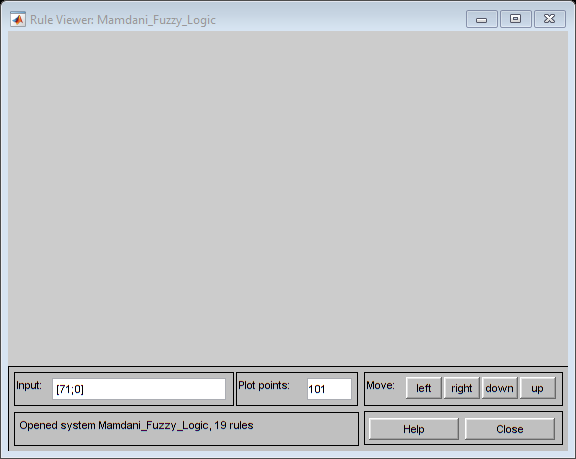

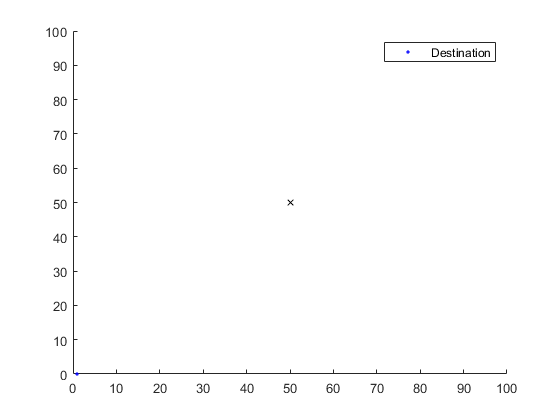

while (~atDestination)
    nextGen = calculateNextGen(fis, currentLocation, currentAngle, destinationLocation); % calculate next generation of linear & angular velocities
    linear_velocity = nextGen(1);
    angular_velocity = nextGen(2);
    currentAngle = getNextTheta(angular_velocity, currentAngle);
    currentLocation = getNextLocation(linear_velocity, currentLocation, currentAngle);
    if (currentLocation(1) > 100)
        currentLocation(1) = 100;
    end
    if (currentLocation(2) > 100)
        currentLocation(2) = 100;
    end
    if (currentLocation(1) < 0)
        currentLocation(1) = 0;
    end
    if (currentLocation(2) < 0)
        currentLocation(2) = 0;
    end
    if (currentAngle < -2*pi)
        currentAngle = -2*pi;
    end
    if (currentAngle > 2*pi)
        currentAngle = 2*pi;
    end
    if (currentAngle == 2*pi || currentAngle == -2*pi)
        currentAngle = 0;
    end
    distance = calculateDistance(currentLocation, destinationLocation);
    atDestination = isAtDestination(currentLocation, destinationLocation);
    visualize(fis, currentLocation, currentAngle, destinationLocation)
    % output linear_velocity, angular_velocity, and membership function
    % weights
end


clf % clear plot
scatter(currentLocation(:,1),currentLocation(:,2), '.b'); % plot currentLocation as a point
scatter(destinationLocation(:,1),destinationLocation(:,2), 'xk','DisplayName', 'Destination'); % plot destinationLocation as a point
legend({'Destination'});

%

%

% 

% calculateNextGen
%
% parameters: fis
%             currentLocation
%             currentAngle
%             destinationLocation
% return: next generation of linear_velocity & angular_velocity

function nextGen = calculateNextGen(fis, currentLocation, currentAngle, destinationLocation)
    phi = calculatePhi(currentAngle, currentLocation, destinationLocation);
    phi = phi(1);
    distance = calculateDistance(currentLocation, destinationLocation);
    nextGen = evalfis(fis, [distance, phi]);
end


% visualize
%
% draws the plot of the robot on the plane AND waits 0.100 s before
% returning
%
% parameters: currentLocation
%             currentAngle
%             destinationLocation
function visualize(fis, currentLocation, currentAngle, destinationLocation)   
    hold on
    axis manual  
    axis([0,100,0,100])
    f1 = scatter(currentLocation(:,1),currentLocation(:,2), '.b', 'DisplayName', 'Robot'); 
    scatter(destinationLocation(:,1),destinationLocation(:,2), 'xk', 'DisplayName', 'Destination');
    xlabel = 'X';
    ylabel = 'Y';
    legend({'Destination'});
    %currentLocationVector = [currentLocation(1)+cos(currentAngle), currentLocation(2)+sin(currentAngle)];
    %f3 = line(currentLocation, currentLocationVector);
    pause(0.100); % pause execution for 100 ms
    delete(f1);
    %delete(f3);
    %hold off
end

% calculatePhi
%
% parameters: currentAngle, currentLocation, destinationLocation
% return: phi, the angle between the robot and the destination
function phi = calculatePhi(currentAngle, currentLocation, destinationLocation)
    currentLocationVec = destinationLocation - currentLocation;
    destinationVec = [cos(currentAngle), sin(currentAngle)];
    temp = dot(destinationVec, currentLocationVec)/(norm(destinationVec)*norm(currentLocationVec));
    if (temp >= 1)
        temp = 1;
    end
    if (temp <= -1)
        temp = -1;
    end
    phi = acos(temp);
    phi = phi(1);
end

% calculateDistance
%
% calculates the distance between two points
%
% parameters: current_coords
%             destination
% return: distance between two points
function distance = calculateDistance(current_coords, destination)
    temp = current_coords-destination;
    temp = temp.^2;
    distance = sqrt(temp(1) + temp(2));
end


% getNextLocation
%
% parameters: linear_velocity
%             currentLocation
%             theta
function nextLocation = getNextLocation(linear_velocity, currentLocation, theta)
    delta_t = 0.100; % change in time = 100 ms
    delta_x = linear_velocity*delta_t;
    delta_x_x = delta_x * cos(theta);
    delta_x_y = delta_x * sin(theta);
    nextLocation = [currentLocation(1)+delta_x_x currentLocation(2)+delta_x_y];
end

% getNextTheta
%
% parameters: angular_velocity
%             theta               
% return: nextTheta
function nextTheta = getNextTheta(angular_velocity, theta)
    nextTheta = theta + angular_velocity; 
end

% isAtDestination
% 
% parameters: currentLocation
%             destination
% return: boolean, true if robot is at destination, false otherwise
function atDestination = isAtDestination(currentLocation, destination)
    episilon = 0.1;
    dist_xy = destination - currentLocation;
    atDestination = false;
    if (abs(dist_xy(1)) <= episilon)
        if (abs(dist_xy(2)) <= episilon)
            atDestination = true;
        end
    end
end
